%Neural ODE - 2 Generators Interation
%1. Data Generation.
%2. Model Parameters.
%3. Neural ODE - Training Options.
%4. Model Evaluation.


%1. Data Generation
%1.1 Network Setup - 2-Classical SG system.
addpath('C:\Users\LEGION\Documents\GitHub\guilda');
addpath('C:\Users\LEGION\Documents\MATLAB\Examples\R2022a\nnet\TrainNeuralODENetworkWithRungeKuttaODESolverExample');
net = power_network;
numGenerators = 2;
%Branch Definition
branch12 = branch_pi(1,2,[0.010,0.085],0);
net.add_branch(branch12);
%branch23 = branch_pi(2,3,[0.017,0.092],0);
%net.add_branch(branch23);
%Definition of busbar (bus)
shunt = [0,0];
%Definition of busbar 1
bus_1 = bus_slack(2,0,shunt);
net.add_bus(bus_1);
%Definition of busbar 2
bus_2 = bus_PV(0.5,2,shunt);
net.add_bus(bus_2);
%Definition of busbar 3
%bus_3 = bus_PQ(-3,0,shunt);
%net.add_bus(bus_3);
%Definition of grid frequency
omega0 = 60*2*pi;
%1-axis model of synchronous generator added to bus-bar 1
Xd = 1.569;
%Xd_prime = 0.963;
Xq = 0.963;
%Tdo = 5.14;
M = 100;
D = 10;
%mac_data = table(Xd,Xd_prime,Xq,Tdo,M,D);
mac_data = table(Xd,Xq,M,D);
component1 = generator_classical(omega0, mac_data);
net.a_bus{1}.set_component(component1);
%A single axis model of a synchronous generator is also added to busbar 2.
Xd = 1.220; 
%Xd_prime = 0.667; 
Xq = 0.667; 
%Tdo = 8.97; 
M = 12; 
D = 10;
%mac_data = table(Xd,Xd_prime,Xq,Tdo,M,D);
mac_data = table(Xd,Xq,M,D);
comp2 = generator_classical(omega0, mac_data);
net.a_bus{2}.set_component(comp2);
%A constant impedance model is added to bus-bar 3
%comp3 = load_impedance();
%net.a_bus{3}.set_component(comp3);
%Running tidal current calculations
net.initialize
%Aside ~Derivation of admittance matrix~.
net.get_admittance_matrix;
Y = full(net.get_admittance_matrix);
%-----------------------------------------------------------------------------------------------------
%1.2 Network Simulation
option = struct();
option.linear = false;
option.x0_sys = net.x_equilibrium;
time = [0,0.1,60]; %Just to make it easier for the solver.
u_idx = 1; %Perturbation to generator 1.
u = [0, 0, 0; 0.1, 0, 0]; %First row = Vfield; Second row = Pmech.
out1 = net.simulate(time,u, u_idx, option); %Analysis Execution
%-----------------------------------------------------------------------------------------------------
%1.3 Plot Results
V1 = out1.V{1}(:,1) + 1j* out1.V{1}(:,2);
I1 = out1.I{1}(:,1) + 1j* out1.I{1}(:,2);
V2 = out1.V{2}(:,1) + 1j* out1.V{2}(:,2);
I2 = out1.I{2}(:,1) + 1j* out1.I{2}(:,2);
sampling_time = out1.t;
delta1 = out1.X{1}(:,1);
omega1 = out1.X{1}(:,2);
%E1 = out.1X{1}(:,3);
delta2 = out1.X{2}(:,1);
omega2 = out1.X{2}(:,2);
figure;
hold on;
plot(sampling_time, omega1,'LineWidth',1.5)
plot(sampling_time, omega2,'LineWidth',1.5)
%arrayfun(@(idx) plot(out1.t,out1.X{idx}(:,2), 'LineWidth',1.5),1:numGenerators);
xlabel('Time [s]','FontSize',10);
ylabel('Frequency Deviation (\omega)','FontSize',10);
xlim([0,20])
legendEntries = cell(1, numGenerators);
for i = 1:numGenerators
    legendEntries{i} = sprintf('Generator %d', i);
end
legend(legendEntries)
title('Frequency deviation of each synchronous generator','FontSize',10)
hold off
%Voltages
% plot(out1.t,abs(V1),out1.t,abs(V2),'LineWidth',2)
% legend({'V_1','V_2'})
% xlabel('Time [s]')
% ylabel('Magnitude [p.u.]')
%-----------------------------------------------------------------------------------------------------
%1.4 Adding a Controller
% Adding a controller to the power system
% %Define AGC controller
% controller = controller_broadcast_PI_AGC(net,1:2,1:2,-10,-500);
% %Assign controller class to power system
% net.add_controller_global(controller);
% %Analysis Execution
% out2 = net.simulate(time,u,u_idx,option);
% %Plot Results
% figure;
% hold on;
% arrayfun(@(idx) plot(out2.t,out2.X{idx}(:,2), 'LineWidth',1.5),1:numGenerators);
% xlabel('Time [s]','FontSize',10);
% ylabel('Frequency Deviation','FontSize',10);
% legendEntries = cell(1, numGenerators);
% for i = 1:numGenerators
%     legendEntries{i} = sprintf('Generator %d', i);
% end
% legend(legendEntries)
% title('Frequency deviation of each synchronous generator','FontSize',15)
% hold off
%-----------------------------------------------------------------------------------------------------
%1.5 Compare Plots without and with controller
%% Comparison plots before and after adding the controller
% figure; hold on;
% plot(out1.t, out1.X{2}(:,2),'Color','#A2142F','LineWidth',1.5)
% plot(out1.t, out1.X{1}(:,2),'Color','#EDB120','LineWidth',1.5)
% plot(out2.t, out2.X{2}(:,2),'Color','#0072BD','LineWidth',1.5)
% plot(out2.t, out2.X{1}(:,2),'Color','#77AC30','LineWidth',1.5)
% xlabel('Time [s]','FontSize',15);
% ylabel('Frequency Deviation','FontSize',15);
% legend({'Frequency deviation of Generator 2 (without AGC)','Frequency deviation of Generator 1 (without AGC)',...
%         'Frequency deviation of Generator 2 (with AGC)','Frequency deviation of Generator 1 (with AGC)'},...
%         'Location','east')
% title('Frequency Deviation Synchronous Generator','FontSize',20)
% hold off

%2. Model Parameters
xTrain = [delta1, omega1, delta2, omega2];
xTrain = xTrain';
x0 = xTrain(1:4,1);
neuralOdeTimesteps = 120;
t = out1.t;
dt = t(2);
[numTimeSteps, ~] = size(t);
t = t';
timespan = linspace(0,60,numTimeSteps);
timesteps = (0:neuralOdeTimesteps)*dt;

neuralOdeParameters = struct;

stateSize = size(xTrain,1);
hiddenSize = 20;

neuralOdeParameters.fc1 = struct; %Fully Connected Layer 1
sz = [hiddenSize stateSize]; %Size of the learnable parameters
neuralOdeParameters.fc1.Weights = initializeGlorot(sz,hiddenSize,stateSize);
neuralOdeParameters.fc1.Bias = initializeZeros([hiddenSize 1]);

neuralOdeParameters.fc2 = struct; %Fully Connected Layer 2
sz = [stateSize hiddenSize];
neuralOdeParameters.fc2.Weights = initializeGlorot(sz,stateSize,hiddenSize);
neuralOdeParameters.fc2.Bias = initializeZeros([stateSize 1]);

neuralOdeParameters.fc1
neuralOdeParameters.fc2

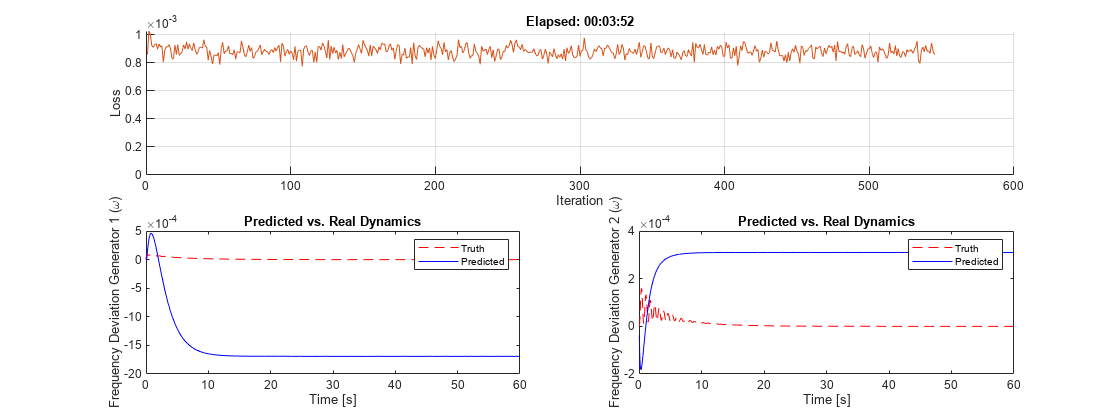

%3. Neural ODE - Training Options
%Details of model in odeModel.m, model.m, modelLoss.m, createMiniBatch.m,
%plotTrueAndPredictedSolutions.m.

gradDecay = 0.9;
sqGradDecay = 0.999;
learnRate = 0.002;

numIter = 1200; %Iteration number
miniBatchSize = 600;

%Model Training Plotting Options
plotFrequency = 50;
f = figure;
f.Position(3) = 2*f.Position(3); %Just make the width 2 times larger.
subplot(2,2,[1 2])
C = colororder;
lineLossTrain = animatedline(Color=C(2,:));
ylim([0 inf])
xlabel("Iteration")
ylabel("Loss")
grid on

%Initialize Adam Solver
averageGrad = [];
averageSqGrad = [];

%Train in Loop

numTrainingTimesteps = numTimeSteps;
trainingTimesteps = 1:numTrainingTimesteps;
plottingTimesteps = 2:numTimeSteps; %Exclude the initial step.

start = tic;

for iter = 1:numIter

    %Create  batch
    [X, targets] = createMiniBatch(numTrainingTimesteps, neuralOdeTimesteps, miniBatchSize, xTrain);

    %Evaluate network and compute loss and gradients
    [loss, gradients] = dlfeval(@modelLoss, timesteps, X, neuralOdeParameters, targets);

    %Update network
    [neuralOdeParameters, averageGrad, averageSqGrad] = adamupdate(neuralOdeParameters, gradients,...
        averageGrad, averageSqGrad, iter, learnRate, gradDecay, sqGradDecay);

    %Plot Loss
    subplot(2,2,[1 2])
    currentLoss = double(loss);
    addpoints(lineLossTrain, iter, currentLoss);
    D = duration(0,0,toc(start), Format = 'hh:mm:ss');
    title('Elapsed: ' + string(D));
    drawnow

    %Plot predicted vs real dynamics
    if mod(iter, plotFrequency) == 0 || iter == 1
        subplot(2,2,3)

        %compute solution with NeuralODE-45
        y = dlode45(@odeModel, timespan, dlarray(x0),neuralOdeParameters,DataFormat='CB');
        plot(t(1,:), xTrain(2,:), 'r--');
        hold on
        plot(timespan(1,2:end), y(2,:),'b-');
        hold off
        xlabel('Time [s]');
        ylabel('Frequency Deviation Generator 1 (\omega)');
        title('Predicted vs. Real Dynamics');
        legend('Truth', 'Predicted');

        subplot(2,2,4)
        plot(t(1,:), xTrain(4,:), 'r--');
        hold on
        plot(timespan(1,2:end),y(4,:),'b-');
        xlabel('Time [s]');
        ylabel('Frequency Deviation Generator 2 (\omega)');
        title('Predicted vs. Real Dynamics');
        legend('Truth', 'Predicted');
        hold off

        drawnow
    end
end

%4. Model Evaluation